## HELLO WORLD - DL MATLAB

We first begin by loading our neural network.

net=alexnet

net =   SeriesNetwork with properties:

         Layers: [25×1 nnet.cnn.layer.Layer]
     InputNames: {'data'}
    OutputNames: {'output'}


Let us now define input size of images

input_size = [227,227];

Load and resize sample image

I = imread('peppers.png');

I = 384×512×3 uint8 array
I(:,:,1) =

    62    63    63    65    66    63    61    63    63    64    64    61    65    64    61    62    63    65    65    64    61    64    65    64    66    71    67    65    64    62    68    68    70    70    71    70    68    74    74    70    70    71    71    72    74    70    69    70    67    67    67    69    69    66    67    67    71    70    69    67    68    71    69    70    71    71    71    70    67    68    67    60    57    56    51    46    45    51    54    54    55    58    54    54    57    58    60    60    58    59    57    60    63    67    70    69    70    70    69    71    70    67    68    69    66    67    68    66    67    64    63    65    66    66    65    62    62    66    66    64    63    64    62    65    67    61    64    64    65    65    62    61    65    68    67    65    70    70    65    66    68    68    67    70    70    72    70    70    70    68    70    71    71    71    68    71    73    71    69    70  

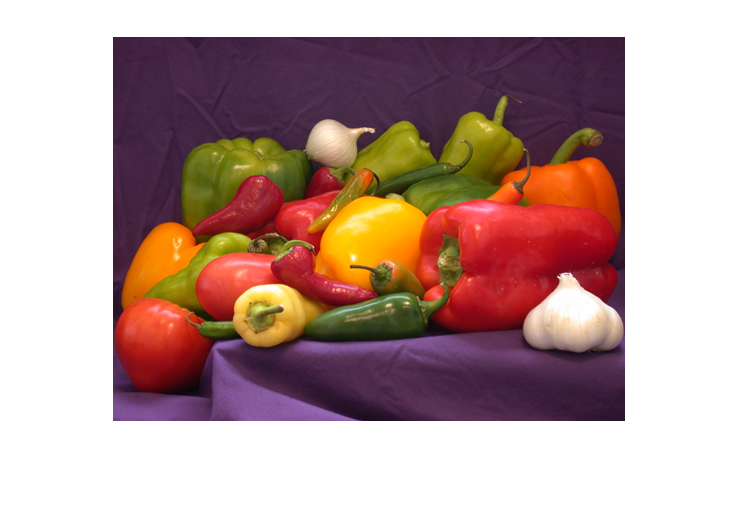

imshow(I)

size(I)

ans =    384   512     3


I = imresize(I,input_size);


Let us now predict the image class using the network

[label,score] = classify(net,I)

label = categorical
     bell pepper 


score = 1×1000 single row vector
    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Top 5 categories

[~,idx] = sort(score,'descend');
idx = idx(1:5);
top5class = net.Layers(end).ClassNames(idx)

top5class = 5×1 cell array
    {'bell pepper'     }
    {'cucumber'        }
    {'orange'          }
    {'Granny Smith'    }
    {'butternut squash'}


top5scores = score(idx)

top5scores = 1×5 single row vector
    0.8330    0.0509    0.0198    0.0188    0.0186
